# Raw signal dimensionality

We searched for two basis sets for the fluorescent data from the lip and tongue.  We are exploring the data with an excitation light of 415 nm.

This script does the same analysis as s_oeDimensionality56, but for the wavelength range from 500-700nm.

**Analysis from 500-700nm**

- From 500-700nm **3 basis functions fit the tongue data and the lip data**, separately.

- To fit the lip data from the tongue data, **we need to use 5 or 6 tongue** dimensions.  We think the tongue dimensions emphasize fitting all the variance in 600-700, and thus we need to go further pick up any benefit for the lip - where all the variance is in 500-600nm.

- To fit the tongue data from the lip data is **impossible**.  The lip data has no components that could represent the porphyrin and chlorphyll found on the tongue.

(See s_oeDimensionality56 for the tissue optics calculation we tried.)

## Initialize the database and ISET

ieInit;

% Wavelength samples
waves = 500:700;

% Read in the database
[T,dataDir] = oeDatabaseCreate;

% Normalize for unit length, using oeReadFiles.
normalizationP = 540;

% This checks the quality of the fit of the data.
dimensionality = [2 3 4 5];


## Read the tongue data

We tried various normalization approaches.  They are all the same.  

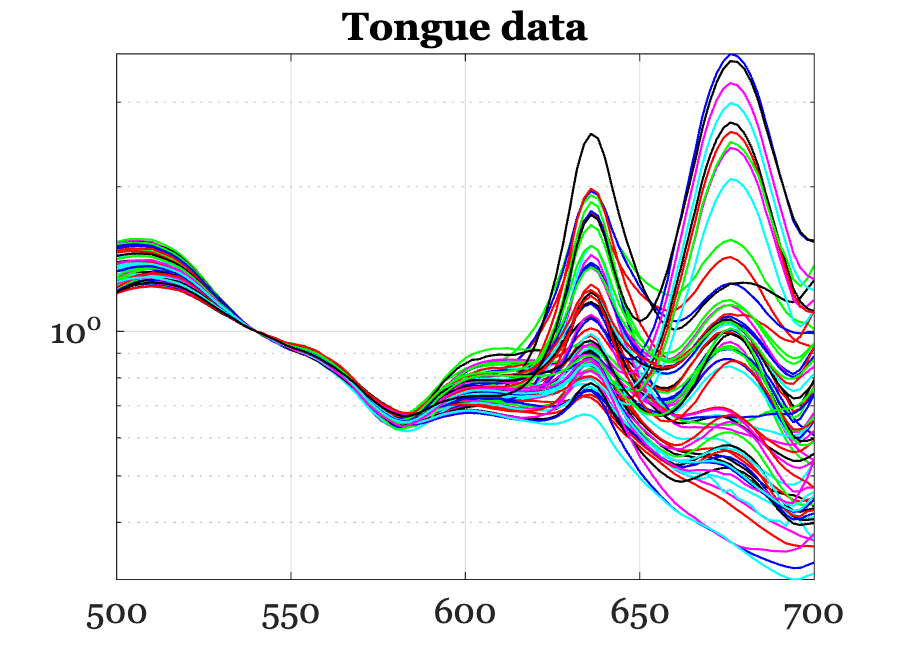

files405 = ieTableGet(T,...
    'ewave',405, ...
    'substrate','tongue');
files415 = ieTableGet(T,...
    'ewave',415, ...
    'substrate','tongue');
filesAll = cat(1,files405,files415);

dataTongue = oeReadFiles(filesAll,'waves',waves,'normalized wave',normalizationP);

ieFigure;
semilogy(waves,dataTongue);
grid on;
title('Tongue data');

## Set the dimensionality of the tongue data

Perform SVD explicitly, rather than using the pca() method.

[UT, ~, ~] = svd(dataTongue, 'econ');


## Plot the accuracy when using the linear model

These graphs show to fit the tongue data, 3 bases are good enough, with  small improvement when we go to 4 or 5.

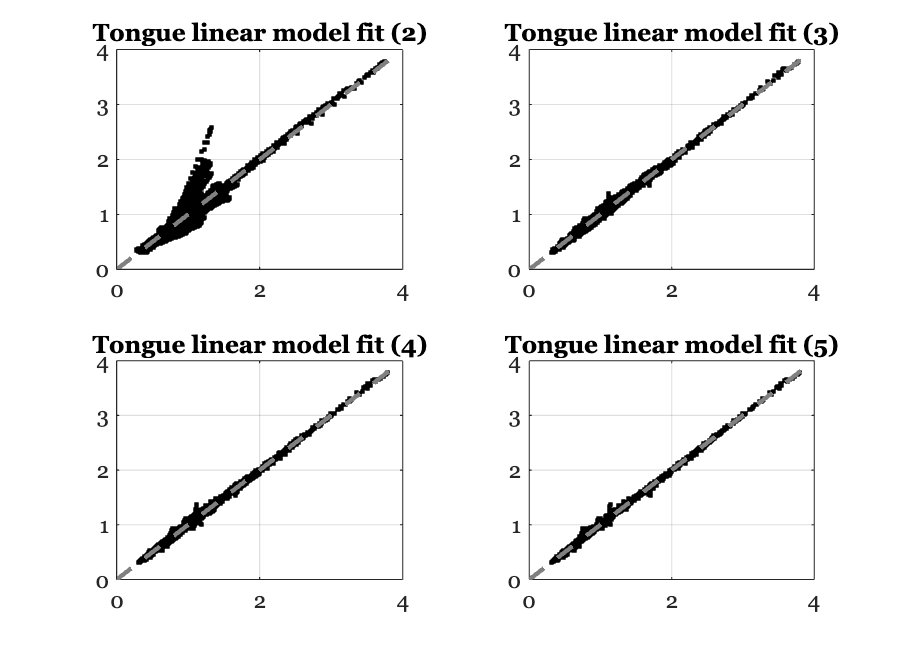

ieFigure;
tiledlayout(2,2);
for dd = dimensionality
    wgts = UT(:,1:dd)'*dataTongue;
    est = UT(:,1:dd)*wgts;
    nexttile;
    plot(est(:),dataTongue(:),'k.');
    identityLine;
    grid on;
    title(sprintf('Tongue linear model fit (%d)',dd));
end

## Read the Lip data

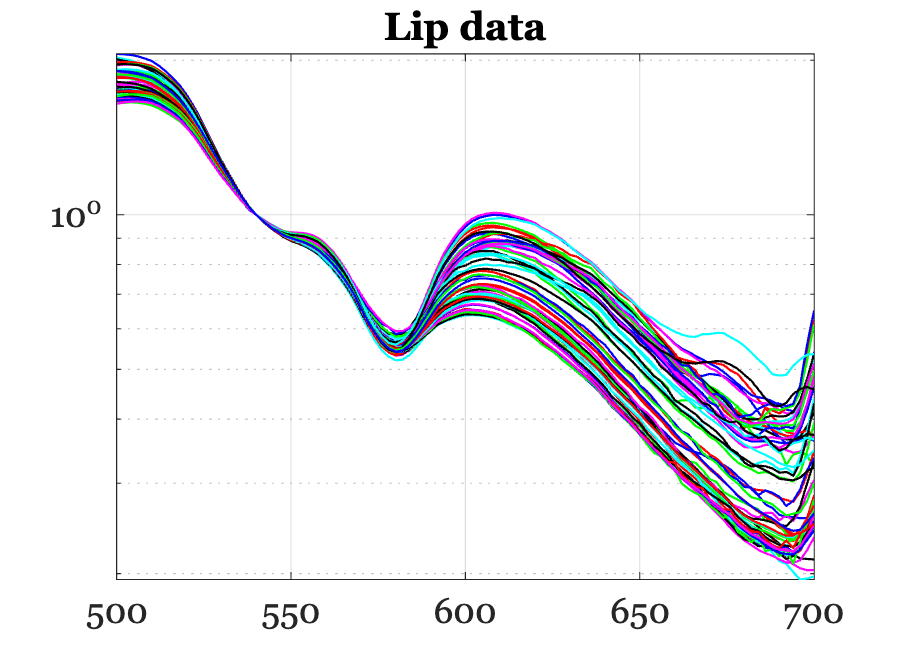

files405 = ieTableGet(T,...
    'ewave',405, ...
    'substrate','lip');
files415 = ieTableGet(T,...
    'ewave',415, ...
    'substrate','lip');
filesAll = cat(1,files405,files415);
dataLip = oeReadFiles(filesAll,'waves',waves,'normalized wave',normalizationP);

ieFigure;
semilogy(waves,dataLip);
grid on;
title('Lip data');

## Fit the lip data from the tongue data

Without first calculating any bases, we can predict the lip data from the tongue data.  No basis approximation.

If they live in the same space, then it shouldn't be a problem.  They both have noise.  Not sure how that helps or hurts.

We find the matrix, M, such that we can multiply the tongue data and predict the lip data.


$${L_d =\;T}_d M$$


The special case would then be to replace the tongue data with a linear model approximation (say finding the basis functions) and use that subspace to make the prediction.  We do that below.

Here we try different dimensions of the tongue and see how well they fit the lip. The lip data are well fit with **five or six tongue dimensions. **

(Perhaps the tongue fits emphasize the 600-700 nm range where there is a lot of variance in the tongue data, and thus the early dimensions do not pick up the important lip features, which are in 500-600 nm.)

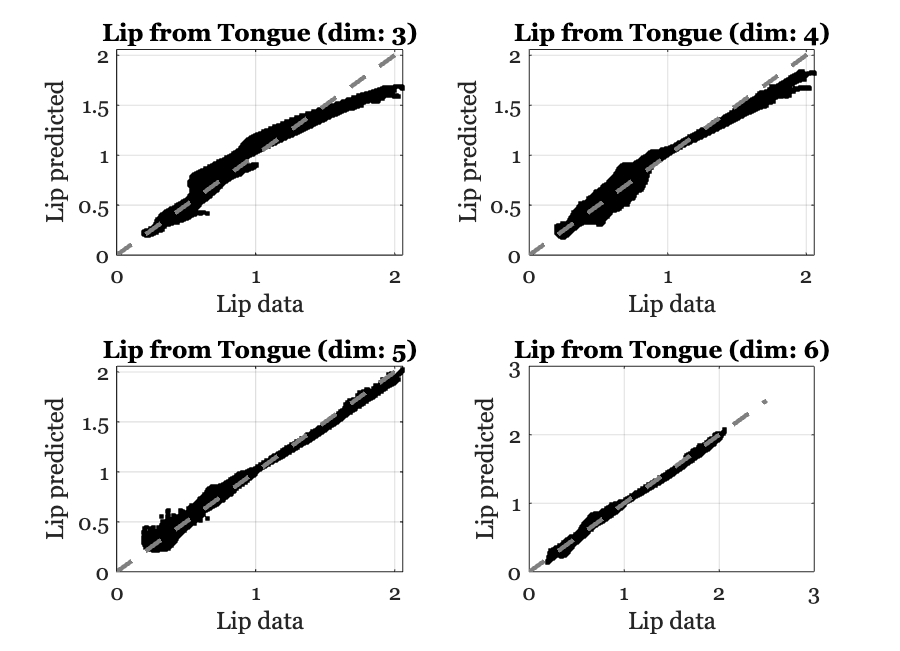

ieFigure;
tiledlayout(2,2)
for ii=3:6
    B = UT(:,1:ii);
    wgts = B'*dataTongue;
    dataTongueReduced = B*wgts;
    M = pinv(dataTongueReduced)*dataLip;
    dataLipP = dataTongueReduced*M;

    nexttile;
    plot(dataLip(:),dataLipP(:),'k.');
    xlabel('Lip data'); ylabel('Lip predicted'); grid on;
    title(sprintf('Lip from Tongue (dim: %d)',ii));
    identityLine;
end

## Find the lip bases

[UL, S, ~] = svd(dataLip, 'econ');


## Fit the lip data with several dimensions

Three dimensions do very well all the way out to 700 nm.

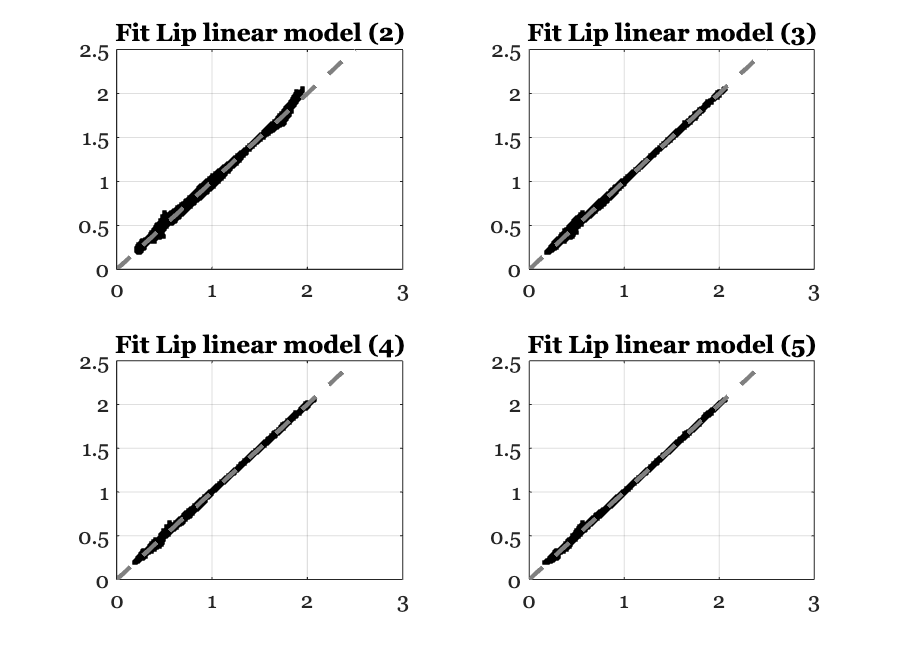

ieFigure;
tiledlayout(2,2)
for dd = dimensionality
    wgts = UL(:,1:dd)'*dataLip;
    est = UL(:,1:dd)*wgts;
    nexttile;
    plot(est(:),dataLip(:),'k.');
    identityLine;
    grid on;
    title(sprintf('Fit Lip linear model (%d)',dd));
end

## Fit the tongue with the lip bases

This really has no chance because nothing about the lip can explain the porphyrins or chlorophyll that are such prominent features of the tongue data.

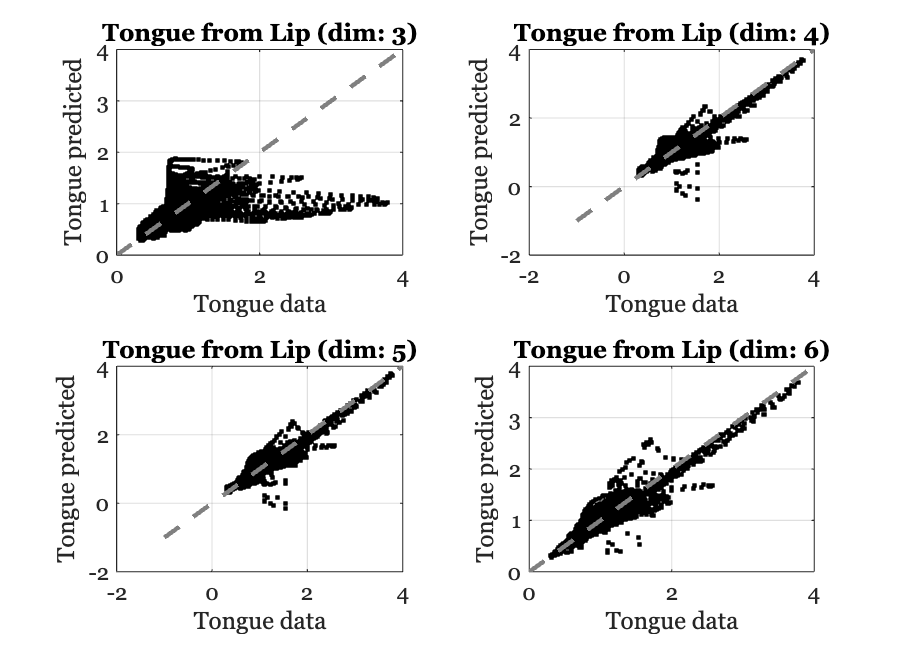

ieFigure;
tiledlayout(2,2)
for ii=3:6
    B = UL(:,1:ii);
    wgts = B'*dataLip;
    dataLipReduced = B*wgts;
    M = pinv(dataLipReduced)*dataTongue;
    dataTongueP = dataLipReduced*M;

    nexttile;
    plot(dataTongue(:),dataTongueP(:),'k.');
    xlabel('Tongue data'); ylabel('Tongue predicted'); grid on;
    title(sprintf('Tongue from Lip (dim: %d)',ii));
    identityLine;
end